## Problem 5

clear;
rng(0);

Generate a dataset comprising a set of $N$ real numbers drawn from the uniform distribution on $[0, 1]$. 

Consider various dataset sizes $N = 5, 10, 20, 40, 60, 80, 100, 500, 10^3 , 10^4$.

N=[5,10,20,40,60,80,100,500,10^3,10^4];  %sizes of datasets

For each $N$, repeat the following experiment $M := 100$ times: 

- first, generate the data, 

- then, compute the average $\hat{\mu}$, and 

- finally, measure the error between the computed average $\hat{\mu}$ and the true mean $\mu$ as $\left| \hat{\mu} - \mu_{true}\right|$.

M=100;
m_true=0.5;    % true mean of uniform distribution

exp_data_1=[];    % experimental data - 100x10 matrix -each column corrresponds to one value of N

for n=N
    mu_v = zeros(M,1);   % stores the difference between empirical and true averages for M iterations
    for i=(1:M)
        mu_v(i) = abs(mean(rand(n,1)) - m_true);   % difference between empirical and true average
    end
    exp_data_1 = [exp_data_1 mu_v];  % append this column to the already stored exp_data
end
disp(exp_data_1);

    0.1786    0.0399    0.2231    0.0119    0.0025    0.0351    0.0373    0.0094    0.0038    0.0004
    0.0691    0.0529    0.0439    0.0701    0.0205    0.0273    0.0570    0.0009    0.0176    0.0029
    0.1742    0.0619    0.0773    0.0054    0.0072    0.0026    0.0044    0.0109    0.0105    0.0013
    0.1462    0.0518    0.0641    0.0107    0.0192    0.0060    0.0080    0.0009    0.0013    0.0007
    0.1307    0.1122    0.0746    0.0113    0.0111    0.0030    0.0134    0.0136    0.0023    0.0047
    0.0440    0.0797    0.0386    0.0523    0.0116    0.0645    0.0427    0.0172    0.0011    0.0003
    0.2684    0.0854    0.0757    0.0070    0.0125    0.0346    0.0119    0.0006    0.0052    0.0010
    0.0640    0.1799    0.0067    0.0363    0.0362    0.0425    0.0133    0.0185    0.0041    0.0000
    0.0136    0.0431    0.0104    0.0184    0.0041    0.0372    0.0093    0.0034    0.0037    0.0001
    0.1091    0.2067    0.0288    0.0168    0.0192    0.0177    0.0010    0.0027    0.0229 

- For the uniform distribution, plot a single graph that shows the distribution of errors (across $M$ repeats) for all values of $N$ using a box-and-whisker plot. You may use the boxplot(.) function in Matlab. 

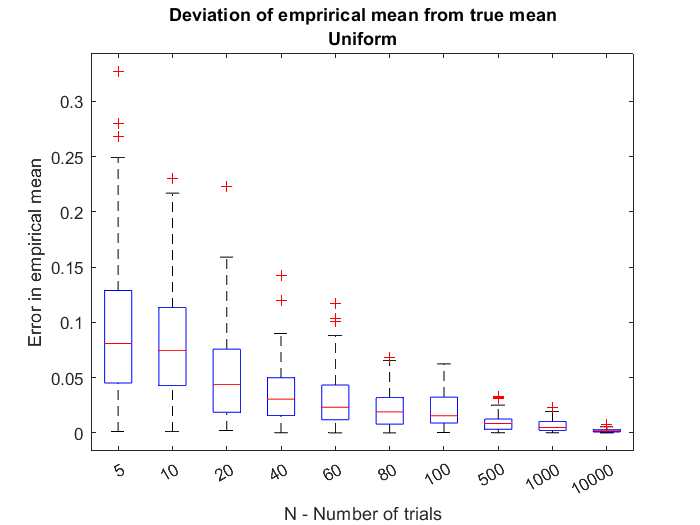

boxplot(exp_data_1,N), xlabel("N - Number of trials"), ylabel("Error in empirical mean"), title({"Deviation of emprirical mean from true mean", "Uniform"});

-  Repeat the above question by replacing the uniform distribution by a Gaussian distribution with $\mu := 0$ and $\sigma^2 := 1$. 

mu=0;     %true mean is 0
sigma=1;   %standard deviation parameter
exp_data_2=[];  % experimental data - 100x10 matrix -each column corrresponds to one value of N

for n=N
    mu_v = zeros(100,1); % stores the difference between empirical and true averages for M iterations
    for i= 1:100
        mu_v(i) = abs(mean(random('Normal',mu,sigma,n,1)) - mu);  % difference between empirical and true average
    end
    exp_data_2 = [exp_data_2 mu_v];  % append this column to the already stored exp_data
end
disp(exp_data_2);

    0.0032    0.1730    0.0260    0.0702    0.0438    0.2045    0.0680    0.0642    0.0709    0.0032
    0.1819    0.0710    0.1438    0.1696    0.0021    0.0290    0.0044    0.0543    0.0237    0.0056
    0.2678    0.0901    0.4400    0.2700    0.0414    0.1650    0.0215    0.0100    0.0585    0.0124
    0.1703    0.0956    0.3105    0.0486    0.1047    0.0188    0.1029    0.0168    0.0226    0.0002
    0.1147    0.3985    0.1746    0.1464    0.0361    0.1319    0.0462    0.0782    0.0012    0.0106
    0.0356    0.2877    0.5468    0.0347    0.0638    0.1584    0.0815    0.0535    0.0249    0.0011
    0.4723    0.4794    0.1786    0.0576    0.0657    0.0626    0.0117    0.0146    0.0468    0.0088
    0.3967    0.5109    0.0254    0.0970    0.0756    0.0688    0.1291    0.0157    0.0213    0.0164
    0.4280    0.1741    0.0003    0.1304    0.1704    0.3048    0.1172    0.0667    0.0099    0.0017
    0.2145    0.4914    0.4528    0.0476    0.0403    0.0019    0.0766    0.1177    0.0118 

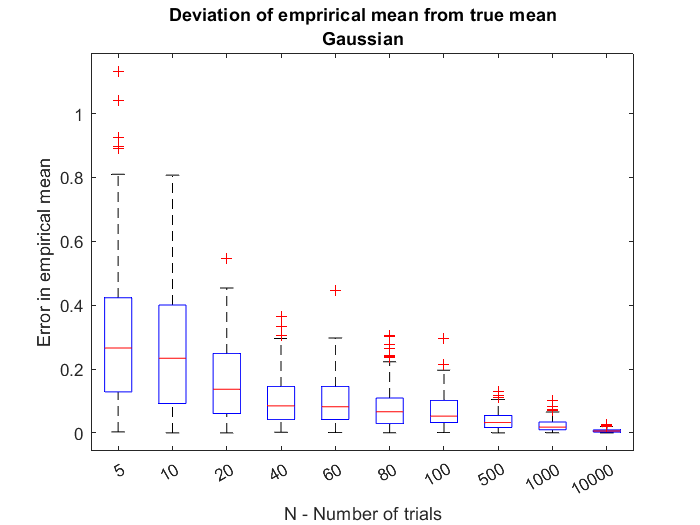


boxplot(exp_data_2,N), xlabel("N - Number of trials"), ylabel("Error in empirical mean"), title({"Deviation of emprirical mean from true mean", "Gaussian"});

-  Interpret what you see in the graphs. What happens to the distribution of error as $N$ increases ? 

When the value of N is small, the data that is generated is more random than the data generated when N is large. So for small N, the spread in the deviations from the true mean are relatively high. As N increases to large enough values(say 1000 and 10000), the mean values obtained over the M(100) iterations are almost equal to the true mean value. In fact, there is barely any data set that is conspicuously farther from 0 when N = 10000; as is evident from the graph.

In conclusion, the distribution of error decreases as N increases.